clear all, close all, clc

## HW04-2

Consider the following Compton scattering incident-

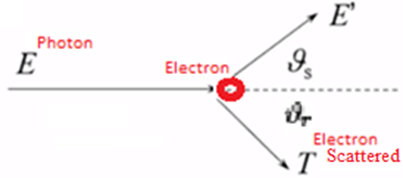

From textbook eq-3.17, we have-

 $T=\frac{2m_e c^2 E^2 {cos}^2 \theta_r }{{{\left(E+m_e c^2 \right)}}^2 -E^2 {cos}^2 \theta_r }$     Here, $\theta_r =$ recoil electron angle

It can be written as-

$T=\frac{2E_r E^2 {cos}^2 \theta_r }{{{\left(E+E_r \right)}}^2 -E^2 {cos}^2 \theta_r }$         Here, $E_r =$ electron's rest mass

Now, we know, maximum KE of compton electron occurs, when there happens a backscatter of photon. Which makes $\theta_r =0$. Thence,


$$T_{\textrm{mx}} =\frac{2E_r E^2 }{{{\left(E+E_r \right)}}^2 -E^2 }$$


Now, let's find the rest mass energy of electron

m_e = 9.1e-31;          % electron mass; kg
c = 3e8;                % light speed; m.s^-1
J_MeV = 1.6e-13;        % J/MeV

So, electron rest mass energy

E_r = m_e*c^2;          % Electron rest mass; J
E_r = E_r /J_MeV        % MeV

E_r = 0.5119

Now, let's find the maximum KE of scattered electron and minimum E'for scattered photon for the given conditiosn.

### (a) E = 100 KeV

E = 100;                % incident gamma energy; KeV
E = E /1e3              % MeV

E = 0.1000

T_mx = 2*E_r*E^2 /((E + E_r)^2 - E^2 )  % max'E of recoil electron; MeV

T_mx = 0.0281

(Ans)

Then, the minimum scattered photon energy-

E_s_mn = E - T_mx       % min'energy of scattered photon; MeV

E_s_mn = 0.0719

(Ans)

Now, let's the following figure from the textbook-

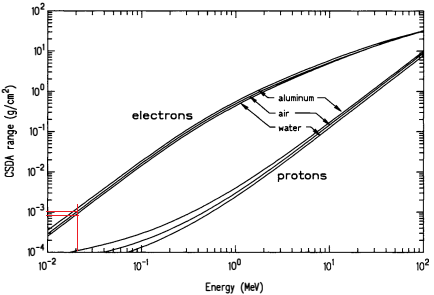

Fig: Range or path length *pA, *in mass units (g/cm2 ), in the continuous slowingdown approximation. 

**range in Water**

From the above figure, for the found T_mx, we see-

L_CSw = 0.0008;         % CSDA range of e', in water; g/cm^2
rh_w = 1;               % density, water; g/cm^3

Now, we know,

$\Lambda \rho =\Lambda_{\textrm{cs}} \;$    $\Lambda_{\textrm{cs}} =$ CSDA range; $\Lambda =$ = range (cm)

Then, we have-

L_w = L_CSw/rh_w        % range; cm

L_w = 8.0000e-04

(Ans)

**range in Air**

L_CSa = 0.001;          % CSDA range of e', in air; g/cm^2
rh_a = 1e-3;            % density, air; g/cm^3
L_a = L_CSa/rh_a        % range; cm

L_a = 1

(Ans)

### (b) E = 1 MeV

E = 1;                  % MeV
T_mx = 2*E_r*E^2 /((E + E_r)^2 - E^2 )      % Max' E of recoil e'; MeV

T_mx = 0.7962

(Ans)

Then, the minimum scattered photon energy-

E_s_mn = E - T_mx       % MeV

E_s_mn = 0.2038

(Ans)

Now, let's use the following figure-

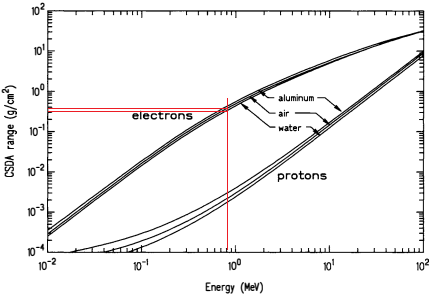

**range in Water**

From the above figure, for the found T_mx, we see-

L_CSw = 0.03;           % CSDA range of e', in water; g/cm^2
rh_w = 1;               % density, water; g/cm^3
L_w = L_CSw/rh_w        % range; cm

L_w = 0.0300

(Ans)

**range in Air**

L_CSa = 0.04;           % CSDA range of e', in air; g/cm^2
rh_a = 1e-3;            % density, air; g/cm^3
L_a = L_CSa/rh_a        % range; cm

L_a = 40

(Ans)

### (b) E = 10 MeV

E = 10;                 % MeV
T_mx = 2*E_r*E^2 /((E + E_r)^2 - E^2 )      % Max' E of recoil e'; MeV

T_mx = 9.7504

(Ans)

Then, the minimum scattered photon energy-

E_s_mn = E - T_mx       % MeV

E_s_mn = 0.2496

(Ans)

Now, let's use the following figure-

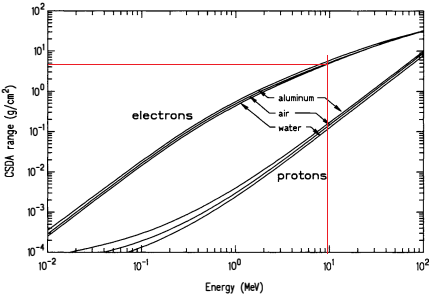

**range in Water**

From the above figure, for the found T_mx, we see-

L_CSw = 4.75;           % CSDA range of e', in water; g/cm^2
rh_w = 1;               % density, water; g/cm^3
L_w = L_CSw/rh_w        % range; cm

L_w = 4.7500

(Ans)

**range in Air**

L_CSa = 4.75;           % CSDA range of e', in air; g/cm^2
rh_a = 1e-3;            % density, air; g/cm^3
L_a = L_CSa/rh_a        % range; cm

L_a = 4750

(Ans)

## HW04-3

### (a)

Given,

A = 56;         % Atomic mass of Fe-56
Q = -0.845;     % Q value of interaction

We know, for inelastic scattering to occur-

$E_t =-\frac{A+1}{A}Q$        $E_t =$ threshold energy of incident neutron. 

E_t = -(A+1)/A *Q      % threshold value for inelastic collisoin; MeV

E_t = 0.8601

(Ans)

### (b)

Using the following equation from the textbook, gives minimum value of incident E, which creates scatter at certain angle-


$$E_{min} =\frac{A{\left(A+1\right)}Q}{{\omega_s }^2 +A^2 -1}$$


th = 45;            % scatter angle
 th = deg2rad(th);  % radian coversion
w_s = cos(th);      % cosine of scatter

Then-

    Dnm = w_s^2 + A^2 -1;   % denominator
E_45 = -A*(A+1)*Q / Dnm     % min E for scattering @ 45 deg; MeV

E_45 = 0.8602

(Ans)

similarly, for 90 deg angle of  scatter-

th = 90;            % scatter angle
 th = deg2rad(th);  % radian coversion
w_s = cos(th);      % cosine of scatter

    Dnm = w_s^2 + A^2 -1;   % denominator
E_45 = -A*(A+1)*Q / Dnm     % min E for scattering @ 90 deg; MeV

E_45 = 0.8604

(Ans)

### (c)

Let's  use the eq. (3.25) from the textbook

 
$$\sqrt{E\prime }=\frac{1}{A+1}\left(\omega_s \sqrt{E}\pm \ \sqrt{E{\left({\omega_s }^2 +A^2 -1\right)}+A{\left(A+1\right)}Q}\right.$$


Here,

Q = -0.845;         % MeV
A = 56;             % mass number
th = 45;            % angle of scatter
 th = deg2rad(45);
w_s = cos(th);      % cosine of scatter

Let's define the range of incident neutron energy, E

E = linspace(0, 200, 201);      % incident nu'energy; MeV

Then, let's build the equation-

    T1 = w_s .*sqrt(E);                 % defining terms 
    T2 = E *(w_s^2 + A^2 -1) + A*(A+1)*Q;
E_s1 = ( 1/(A+1) *(T1 + sqrt(T2)) ).^2;     % upper range of E'; MeV
E_s2 = ( 1/(A+1) *(T1 - sqrt(T2)) ).^2;     % lower range of E'; MeV

Now, let's plot E vs E'

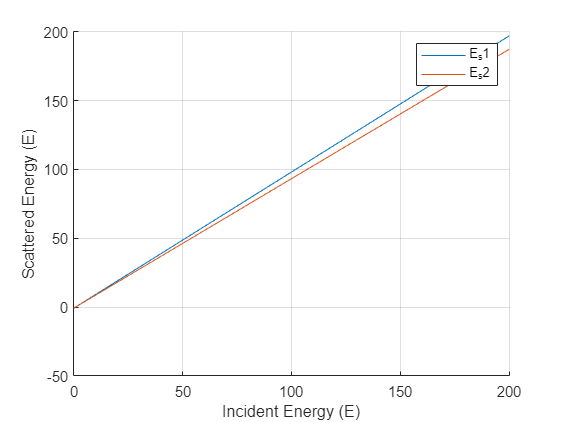

figure()
grid on, hold on
plot(E, E_s1, 'DisplayName', 'E_s1')
plot(E, E_s2, 'DisplayName', 'E_s2')
legend 
xlabel('Incident Energy (E)');
ylabel('Scattered Energy (E)');

The two lines encapsulate the range of E' for different values of incident E. This curve shows that a very little energy is absorbed by the nuclide. 

### (d)

We have here, from book, eq (3.32)

$\omega_c =-\gamma {\left(1-{\omega_s }^2 \right)}\pm \ \omega_s \sqrt{1-\gamma^2 \left(1-{\omega_s }^2 \right)}$         $\omega_c =$ scatter cosein in COM based system

where, $\gamma ={{\left(A^2 +\frac{A{\left(A+1\right)}Q}{E}\right)}}^{-\frac{1}{2}}$

Let's build the equation-

gm = (A^2 + A*(A+1)*Q ./E).^-0.5;     % gamma const.

th = 45; th = deg2rad(th);           % scatter angle
w_s = cos(th);
w_c1 = -gm*(1-w_s^2) + w_s .*sqrt(1 - gm.^2 *(1 - w_s)^2);
w_c2 = -gm*(1-w_s^2) - w_s .*sqrt(1 - gm.^2 *(1 - w_s)^2);

Now, let's plot them

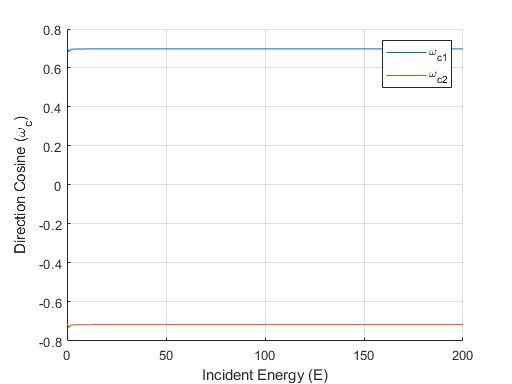

figure()
grid on, hold on
plot(E, w_c1, 'DisplayName', '\omega_{c1}')
plot(E, w_c2, 'DisplayName', '\omega_{c2}')
legend 
xlabel('Incident Energy (E)');
ylabel('Direction Cosine (\omega_c)');

### (e)

Again, let's use the following equation-


$$\sqrt{E\prime }=\frac{1}{A+1}\left(\omega_s \sqrt{E}\pm \ \sqrt{E{\left({\omega_s }^2 +A^2 -1\right)}+A{\left(A+1\right)}Q}\right.$$


**for E = 2 MeV**

Given, the incident energy

E1 = 2;          % MeV

Let's define the range of cosine

w_s = linspace(-1, 1, 101);     % cosine of scatter

Then, let's build the equation

    T1 = w_s .*sqrt(E1);                 % defining terms 
    T2 = E1 *(w_s.^2 + A^2 -1) + A*(A+1)*Q;
E_s11 = ( 1/(A+1) *(T1 + sqrt(T2)) ).^2;     % upper range of E'; MeV
E_s21 = ( 1/(A+1) *(T1 - sqrt(T2)) ).^2;     % lower range of E'; MeV

Now, let's plot them E' vs w_s

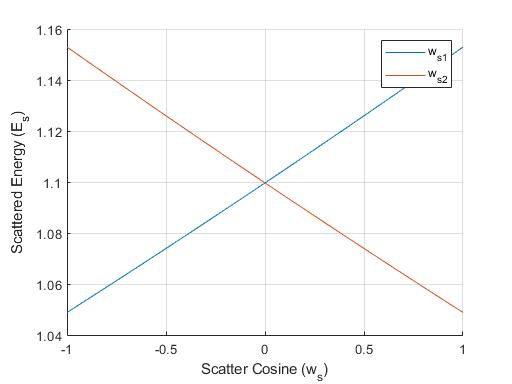

figure()
grid on, hold on
plot(w_s, E_s11, 'DisplayName', 'w_{s1}')
plot(w_s, E_s21, 'DisplayName', 'w_{s2}')
legend 
xlabel('Scatter Cosine (w_s)');
ylabel('Scattered Energy (E_s)'); 

**for E = 1 MeV**

Given, the incident energy

E2 = 1;          % MeV

Let's define the range of cosine

w_s = linspace(-1, 1, 101);     % cosine of scatter

Then, let's build the equation

    T1 = w_s .*sqrt(E2);                 % defining terms 
    T2 = E2 *(w_s.^2 + A^2 -1) + A*(A+1)*Q;
E_s12 = ( 1/(A+1) *(T1 + sqrt(T2)) ).^2;     % upper range of E'; MeV
E_s22 = ( 1/(A+1) *(T1 - sqrt(T2)) ).^2;     % lower range of E'; MeV

Now, let's plot them E' vs w_s

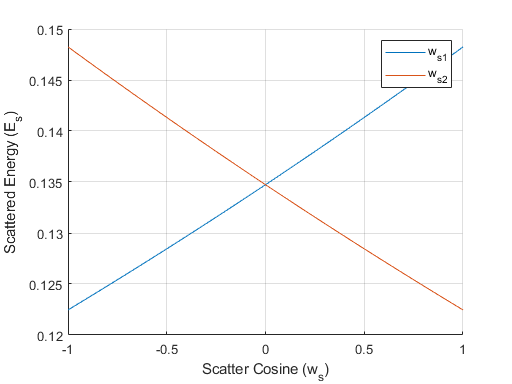

figure()
grid on, hold on
plot(w_s, E_s12, 'DisplayName', 'w_{s1}')
plot(w_s, E_s22, 'DisplayName', 'w_{s2}')
legend 
xlabel('Scatter Cosine (w_s)');
ylabel('Scattered Energy (E_s)'); 

**for E = 0.860363 MeV**

Given, the incident energy

E3 = 0.860363;          % MeV

Let's define the range of cosine

w_s = linspace(-1, 1, 101);     % cosine of scatter

Then, let's build the equation

    T1 = w_s .*sqrt(E3);                 % defining terms 
    T2 = E3 *(w_s.^2 + A^2 -1) + A*(A+1)*Q;
E_s13 = ( 1/(A+1) *(T1 + sqrt(T2)) ).^2;     % upper range of E'; MeV
E_s23 = ( 1/(A+1) *(T1 - sqrt(T2)) ).^2;     % lower range of E'; MeV

Now, let's plot them E' vs w_s

figure()
grid on, hold on
plot(w_s, E_s13, 'DisplayName', 'w_{s1}')

plot(w_s, E_s23, 'DisplayName', 'w_{s2}')

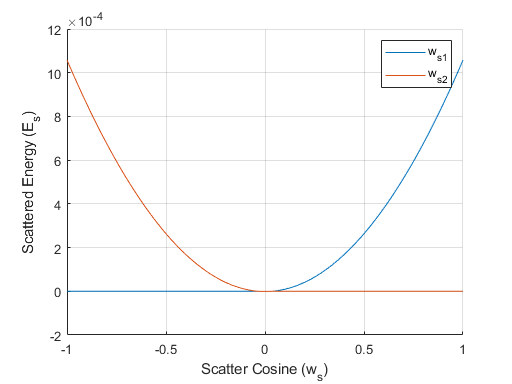

legend 
xlabel('Scatter Cosine (w_s)');
ylabel('Scattered Energy (E_s)');  

**for E = 0.860300 MeV**

Given, the incident energy

E4 = 0.860300;          % MeV

Let's define the range of cosine

w_s = linspace(-1, 1, 101);     % cosine of scatter

Then, let's build the equation

    T1 = w_s .*sqrt(E4);                 % defining terms 
    T2 = E4 *(w_s.^2 + A^2 -1) + A*(A+1)*Q;
E_s14 = ( 1/(A+1) *(T1 + sqrt(T2)) ).^2;     % upper range of E'; MeV
E_s24 = ( 1/(A+1) *(T1 - sqrt(T2)) ).^2;     % lower range of E'; MeV

Now, let's plot them E' vs w_s

figure()
grid on, hold on
plot(w_s, E_s14, 'DisplayName', 'w_{s1}');

plot(w_s, E_s24, 'DisplayName', 'w_{s2}');

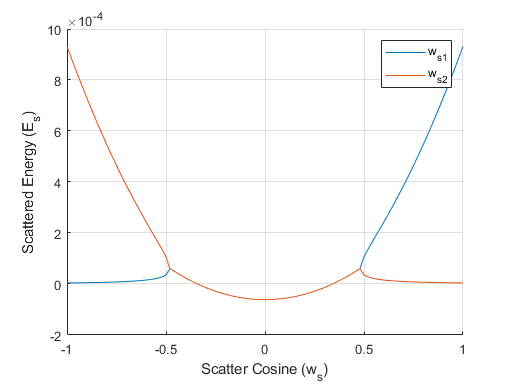

legend 
xlabel('Scatter Cosine (w_s)');
ylabel('Scattered Energy (E_s)'); 

### Combined Plot

Now, let's plot the E' vs w_s vales for different incident energy E of neutron- on the same figure-

figure()
grid on, hold on
plot(w_s, E_s11, 'DisplayName', 'E_s = 2')
plot(w_s, E_s21, 'DisplayName', 'E_s = 2')
plot(w_s, E_s12, 'DisplayName', 'E_s = 1')
plot(w_s, E_s22, 'DisplayName', 'E_s = 1')
plot(w_s, E_s13, 'DisplayName', 'E_s = 0.86304');

plot(w_s, E_s23, 'DisplayName', 'E_s = 0.86304');

plot(w_s, E_s14, 'DisplayName', 'E_s = 0.86303');

plot(w_s, E_s24, 'DisplayName', 'E_s = 0.86304');

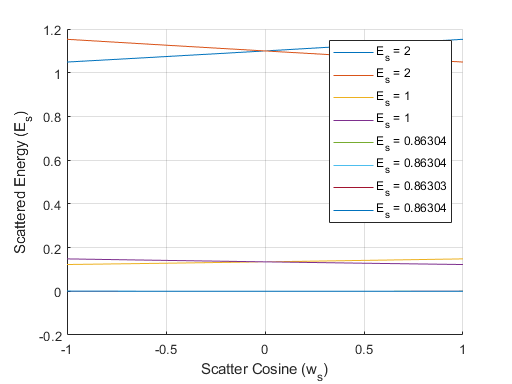

legend 
xlabel('Scatter Cosine (w_s)');
ylabel('Scattered Energy (E_s)'); 

The trend we see here,

When the incident energy is near the threshold amount (E_t = 0.08601) the scattering energy behaves chaotically, OTOH when the incident inergy is large (2 MeV) the scttering range is quite prominent. 